p = [-2/3, 0, 0, 5/3];
roots(p)

ans =   -0.6786 + 1.1754i
  -0.6786 - 1.1754i
   1.3572 + 0.0000i


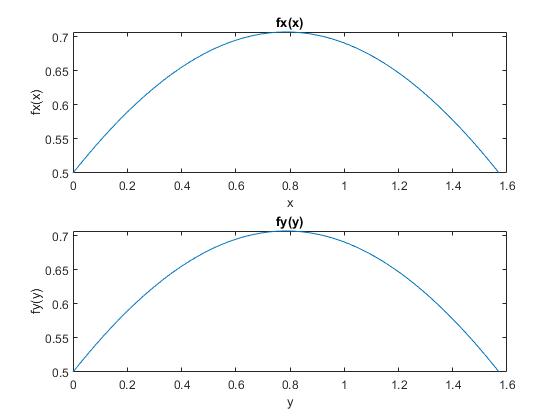


x = linspace(0,pi/2);
y = linspace(0,pi/2);

fx = 1/2*(sin(x)+cos(x));
fy = 1/2*(sin(y)+cos(y));
figure
subplot(2,1,1)
plot(x,fx)
xlabel('x')
ylabel('fx(x)')
title('fx(x)')
subplot(2,1,2)
plot(y,fy)
xlabel('y')
ylabel('fy(y)')
title('fy(y)')

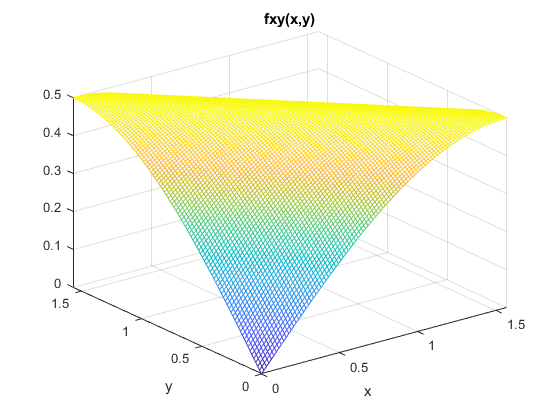

[X,Y] = meshgrid(linspace(0,pi/2));
fxy = 1/2*sin(X+Y);
figure
mesh(X,Y,fxy)
xlabel('x')
ylabel('y')
title('fxy(x,y)')

y = linspace(0,4)

y =          0    0.0404    0.0808    0.1212    0.1616    0.2020    0.2424    0.2828    0.3232    0.3636    0.4040    0.4444    0.4848    0.5253    0.5657    0.6061    0.6465    0.6869    0.7273    0.7677    0.8081    0.8485    0.8889    0.9293    0.9697    1.0101    1.0505    1.0909    1.1313    1.1717    1.2121    1.2525    1.2929    1.3333    1.3737    1.4141    1.4545    1.4949    1.5354    1.5758    1.6162    1.6566    1.6970    1.7374    1.7778    1.8182    1.8586    1.8990    1.9394    1.9798


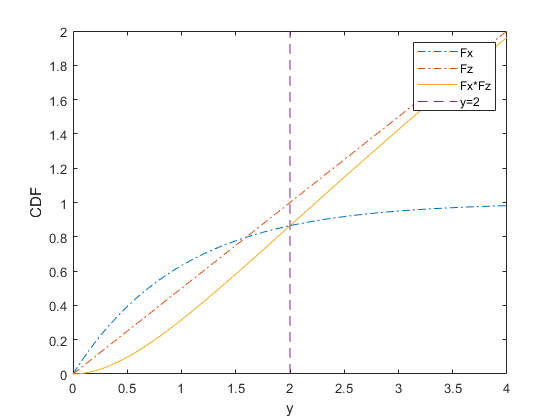

Fx = 1-exp(-y);
Fz = y/2;
figure
plot(y, Fx, '-.')
hold on;
plot(y, Fz, '-.')
plot(y, Fz.*Fx)

plot([2,2],[0,2],'--')
legend('Fx','Fz','Fx*Fz','y=2')
xlabel('y')
ylabel('CDF')

syms theta y
L = 2;
l = 3;

p0 = int(int(1/(pi*L), [l*sin(theta), L]), [0, asin(L/l)])*2;
p0 = eval(p0)

p0 = 0.2214


p2 = int(int(1/(pi*L), [0, l*sin(theta)-L]), [asin(L/l)], pi/2)*2;
p2 = eval(p2)

p2 = 0.1763


p1 = 1 - p0 - p2

p1 = 0.6023


p0_ = int(int(1/(pi*L), [l*sin(theta)-L, l*sin(theta)]), [0, pi]);
eval(p0_)

ans = 1